clear
close all
clc

clear
close all
clc
T = readtable('music_genre.csv');

X=[T.popularity, T.acousticness, T.danceability, T.duration_ms, T.energy, T.instrumentalness, T.liveness, T.loudness, T.speechiness, T.valence, T.tempo];
tempo_mean = nanmean(T.tempo);
tempo_std = nanstd(T.tempo);
X = normalize(X);
X = knnimpute(X, 5);
y=T.music_genre;
T.music_genre=categorical(T.music_genre);
genre=string(categories(T.music_genre));
X1 = X(y==genre(1),:);

figure; 

subplot(4,3,1)
Y = cmdscale(pdist(X1,'euclidean'), 2);
dists_Y = squareform(pdist(Y));
stress = norm(squareform(pdist(X1))-dists_Y, "fro") / norm(squareform(pdist(X1)),"fro");
plot(Y(:,1), Y(:,2), '.', 'markersize', 12);
title(genre(1)+string(' stress ')+string(stress), 'fontsize', 10)
set(gca, 'fontsize', 14)



subplot(4,3,2)
X2=X(y==genre(2),:);
Y = cmdscale(pdist(X2,'euclidean'), 2);
dists_Y = squareform(pdist(Y));
stress = norm(squareform(pdist(X2))-dists_Y, "fro") / norm(squareform(pdist(X2)),"fro");
plot(Y(:,1), Y(:,2), '.', 'markersize', 12);
title(genre(2)+string(' stress ')+string(stress), 'fontsize', 10)
set(gca, 'fontsize', 14)


subplot(4,3,3)
X3=X(y==genre(3),:);
Y = cmdscale(pdist(X3,'euclidean'), 2);
dists_Y = squareform(pdist(Y));
stress = norm(squareform(pdist(X3))-dists_Y, "fro") / norm(squareform(pdist(X3)),"fro");
plot(Y(:,1), Y(:,2), '.', 'markersize', 12);
title(genre(3)+ string(' stress ')+string(stress), 'fontsize', 10)

set(gca, 'fontsize', 14)


subplot(4,3,4)
X4=X(y==genre(4),:);
Y = cmdscale(pdist(X4,'euclidean'), 2);
dists_Y = squareform(pdist(Y));
stress = norm(squareform(pdist(X4))-dists_Y, "fro") / norm(squareform(pdist(X4)),"fro");
plot(Y(:,1), Y(:,2), '.', 'markersize', 12);
title(genre(4)+ string(' stress ')+string(stress), 'fontsize', 10)
set(gca, 'fontsize', 14)



subplot(4,3,5)
X5=X(y==genre(5),:);
Y = cmdscale(pdist(X5,'euclidean'), 2);
dists_Y = squareform(pdist(Y));
stress = norm(squareform(pdist(X5))-dists_Y, "fro") / norm(squareform(pdist(X5)),"fro");
plot(Y(:,1), Y(:,2), '.', 'markersize', 12);
title(genre(5)+ string(' stress ')+string(stress), 'fontsize', 10)
set(gca, 'fontsize', 14)


subplot(4,3,6)
X6=X(y==genre(6),:);
Y = cmdscale(pdist(X6,'euclidean'), 2);
dists_Y = squareform(pdist(Y));
stress = norm(squareform(pdist(X6))-dists_Y, "fro") / norm(squareform(pdist(X6)),"fro");
plot(Y(:,1), Y(:,2), '.', 'markersize', 12);
title(genre(6)+ string(' stress ')+string(stress), 'fontsize', 10)
set(gca, 'fontsize', 14)



subplot(4,3,7)
X7=X(y==genre(7),:);
Y = cmdscale(pdist(X7,'euclidean'), 2);
dists_Y = squareform(pdist(Y));
stress = norm(squareform(pdist(X7))-dists_Y, "fro") / norm(squareform(pdist(X7)),"fro");
plot(Y(:,1), Y(:,2), '.', 'markersize', 12);
title(genre(7)+ string(' stress ')+string(stress), 'fontsize', 10)
set(gca, 'fontsize', 14)


subplot(4,3,8)
X8=X(y==genre(8),:);
Y = cmdscale(pdist(X8,'euclidean'), 2);
dists_Y = squareform(pdist(Y));
stress = norm(squareform(pdist(X8))-dists_Y, "fro") / norm(squareform(pdist(X8)),"fro")

stress = 0.4544

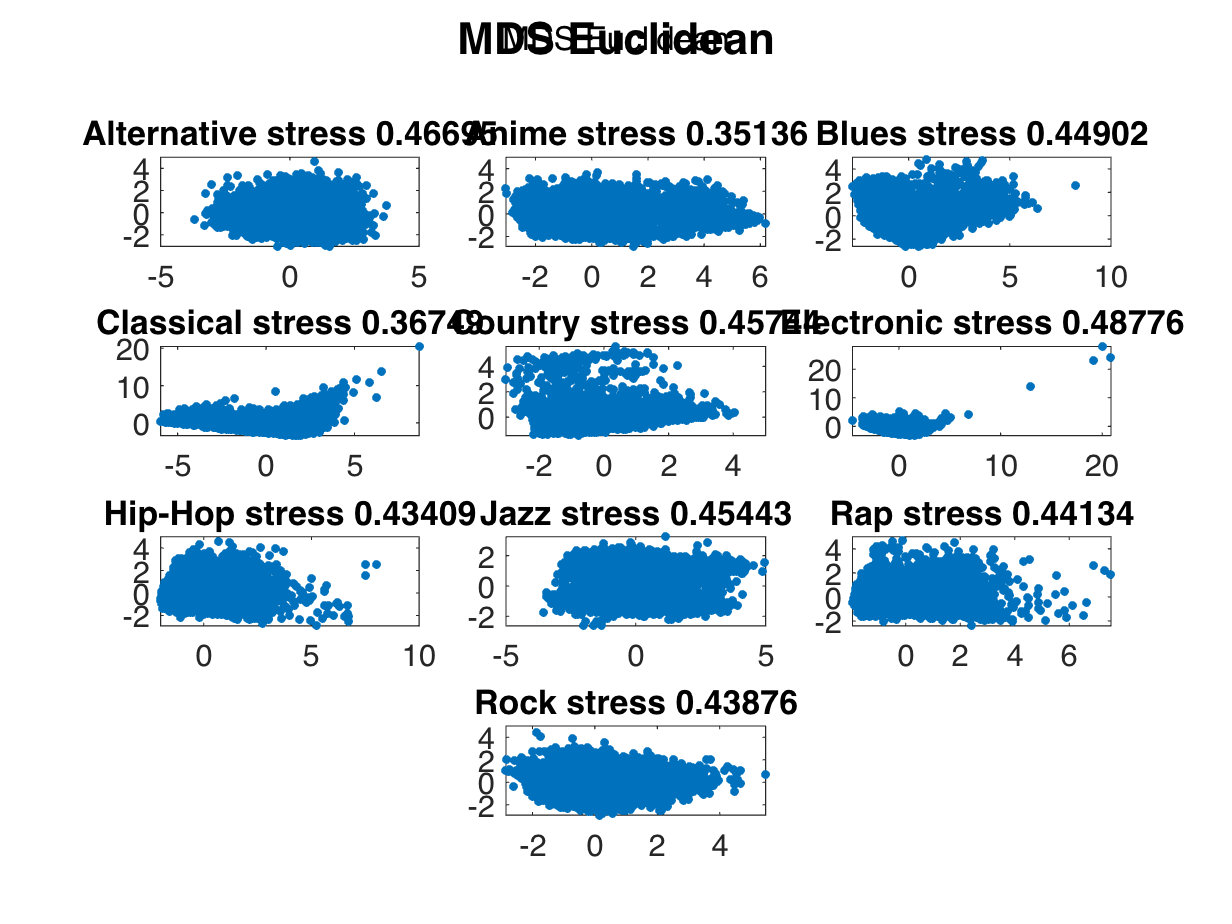

plot(Y(:,1), Y(:,2), '.', 'markersize', 12);
title(genre(8)+ string(' stress ')+string(stress), 'fontsize', 10)
set(gca, 'fontsize', 14)


subplot(4,3,9)
X9=X(y==genre(9),:);
Y = cmdscale(pdist(X9,'euclidean'), 2);
dists_Y = squareform(pdist(Y));
stress = norm(squareform(pdist(X9))-dists_Y, "fro") / norm(squareform(pdist(X9)),"fro");
plot(Y(:,1), Y(:,2), '.', 'markersize', 12);
title(genre(9)+ string(' stress ')+string(stress), 'fontsize', 10)
set(gca, 'fontsize', 14)

subplot(4,3,11)
X10=X(y==genre(10),:);
Y = cmdscale(pdist(X10,'euclidean'), 2);
dists_Y = squareform(pdist(Y));
stress = norm(squareform(pdist(X10))-dists_Y, "fro") / norm(squareform(pdist(X10)),"fro");
plot(Y(:,1), Y(:,2), '.', 'markersize', 12);
title(genre(10)+ string(' stress ')+string(stress), 'fontsize', 10)
set(gca, 'fontsize', 14)
sgtitle('MDS Euclidean', 'fontweight','bold' ,'fontsize', 20 )